Reproduce and explore Fig. 1. First, click run below to load everything needed for other sections to run.

 


% NOTE: This MATLAB live script contains a mixture of code written by
% -- the authors of Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. 
% (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms 
% of bovine spermatozoa. R. Soc. Open Sci. 7: 200769
% (particularly for reproducing Fig. 1)
% -- the members of Cambridge InfertiliTEAM for inFer GW4 network Hackathon


clear
clf

% add folders to path so can e.g. run functions in those folders
addpath('Data',  'Functions',  'Images',  'Movies')

% load all_data.mat 
load_all_data

% load data for figure with real beat; assign beat data to new variable to
% avoid variable name conflict
load('Data/real.mat','beat')
realBeat = beat;

% load data for figure with synthetic beat; assign beat data to new variable
load('Data/synthetic.mat','beat')
syntheticBeat = beat;

% colours for real and synthetic beat figures
cc = importdata('Data/colormap.txt');
inds = 1 : 4 : 100;
cc = cc(inds,:);

% find min and max of all y values in waveform, for purpose of ylim for
% plots
allValues = [];
for i=1:216
    allValues = [allValues; data{i}.cartesian(:,:,2)];
end
waveformMiny = min(allValues,[],"all");
waveformMaxy = max(allValues,[],"all");



Fig. 1(a). Captured frame from a video of a spermatozoon.

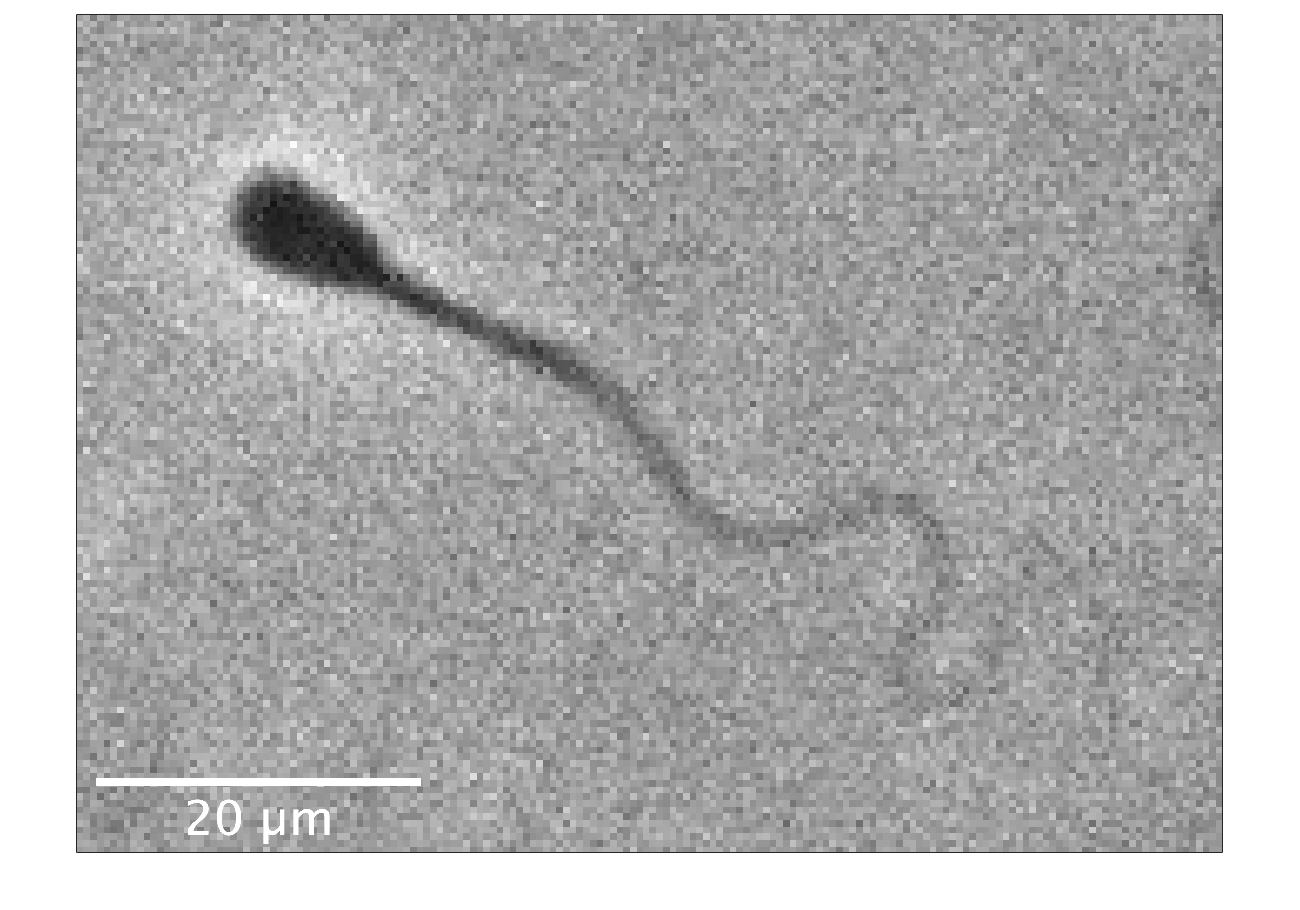

 
figure
imshow( imread('Data/raw.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

Fig. 1(b). Flagellum identified from the captured frame in Fig. 1(a), using automated methodology of Walker BJ, Ishimoto K, Wheeler RJ. 2019 Automated identification of flagella from videomicroscopy via the medial axis transform. Sci. Rep. 9, 5015. (doi:10.1038/s41598-019-41459-9).

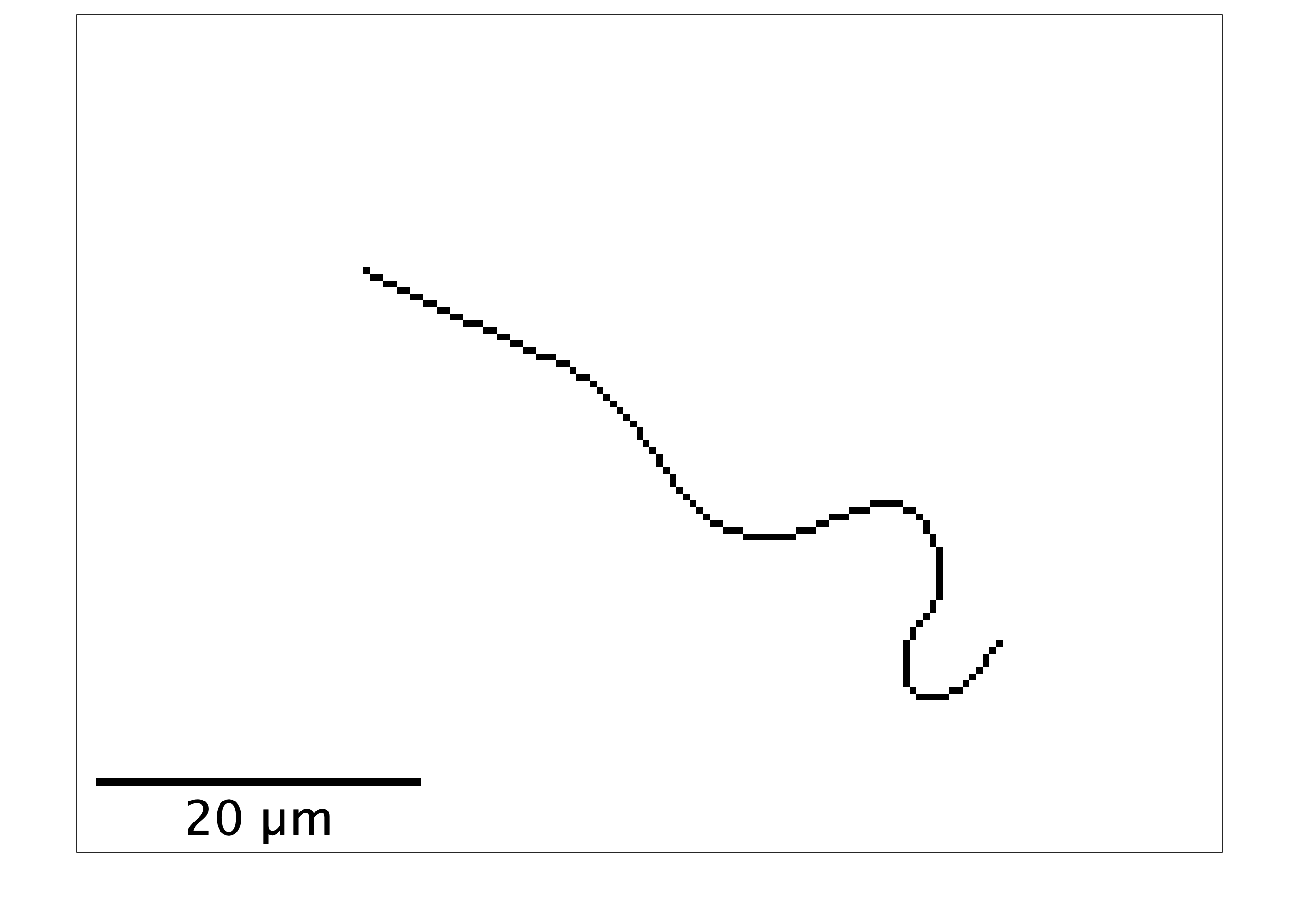

 
figure
imshow( imread('Data/flag.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

Fig. 1(c). Captured waveform over a single beating period. Different colours indicate different timepoints within the period.

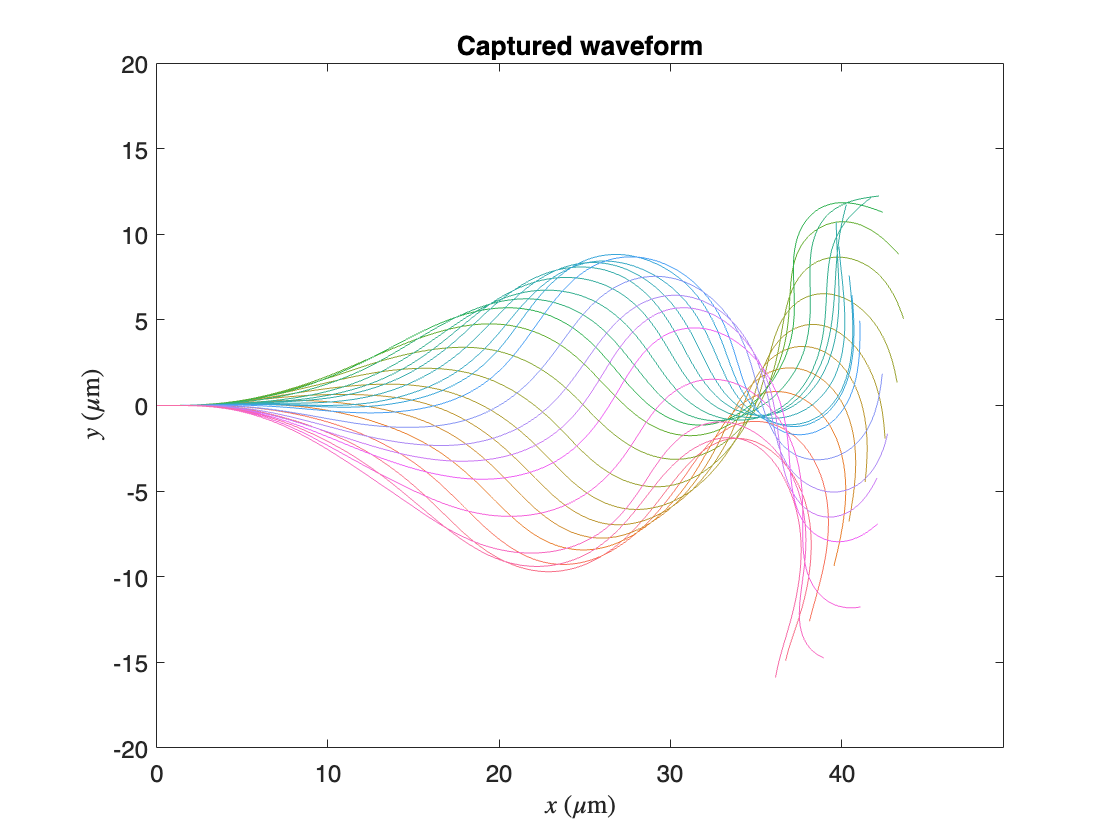

 

figure

h = plot(realBeat.xy(inds,:,1)',realBeat.xy(inds,:,2)');
set(h, {'color'}, num2cell(cc, 2));
axis equal
xlabel('$x$ ($\mu$m)','interpreter','latex')
ylabel('$y$ ($\mu$m)','interpreter','latex')
set(gca,'FontSize',12)
xlims = [0,49.457];
ylims = [-20,20];
xlim(xlims)
ylim(ylims)
set(gca,'XTick',[0 10 20 30 40])
title('Captured waveform')

Animated version of Fig. 1(c). Captured waveform (thick black line) during one beating period. Light grey shows the waveform at all the timepoints during a period.

The first time you click "Run", the animation will play slowly. After that, you can click the "play" button to watch the animation again, and use the dropdown menu to adjust the playback speed.

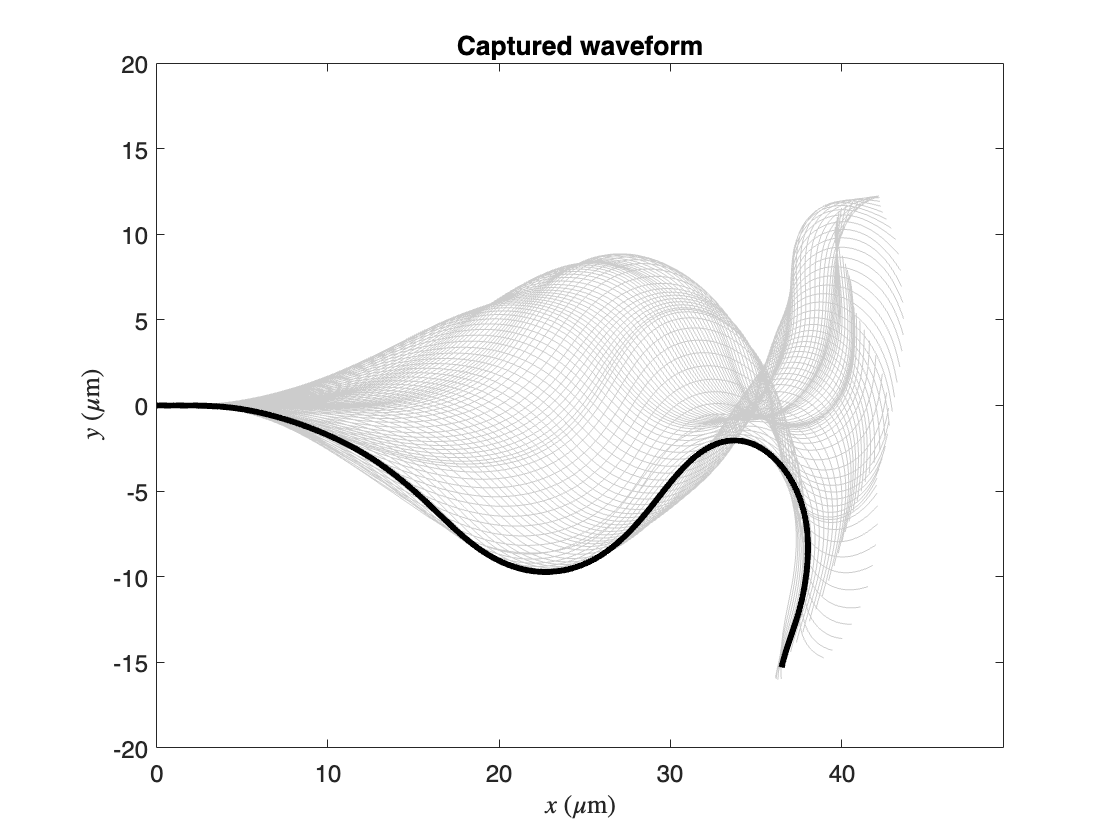

 

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(realBeat.xy(:,:,1)',realBeat.xy(:,:,2)','color','#cccccc')
    hold on
    % plot the waveform at the current timepoint
    plot(realBeat.xy(timepoint,:,1)',realBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',12)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Captured waveform')
    drawnow
end

Explore the dataset from (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms of bovine spermatozoa. R. Soc. Open Sci. 7: 200769. Select a Sperm ID (from 1 to 216). Captured waveform (thick black line) during one beating period. Light grey shows the waveform at all the timepoints during a period. Note that Sperm IDs from 1 to 79 are from sample A (fresh), and from 80 to 216 are from sample B (thawed).

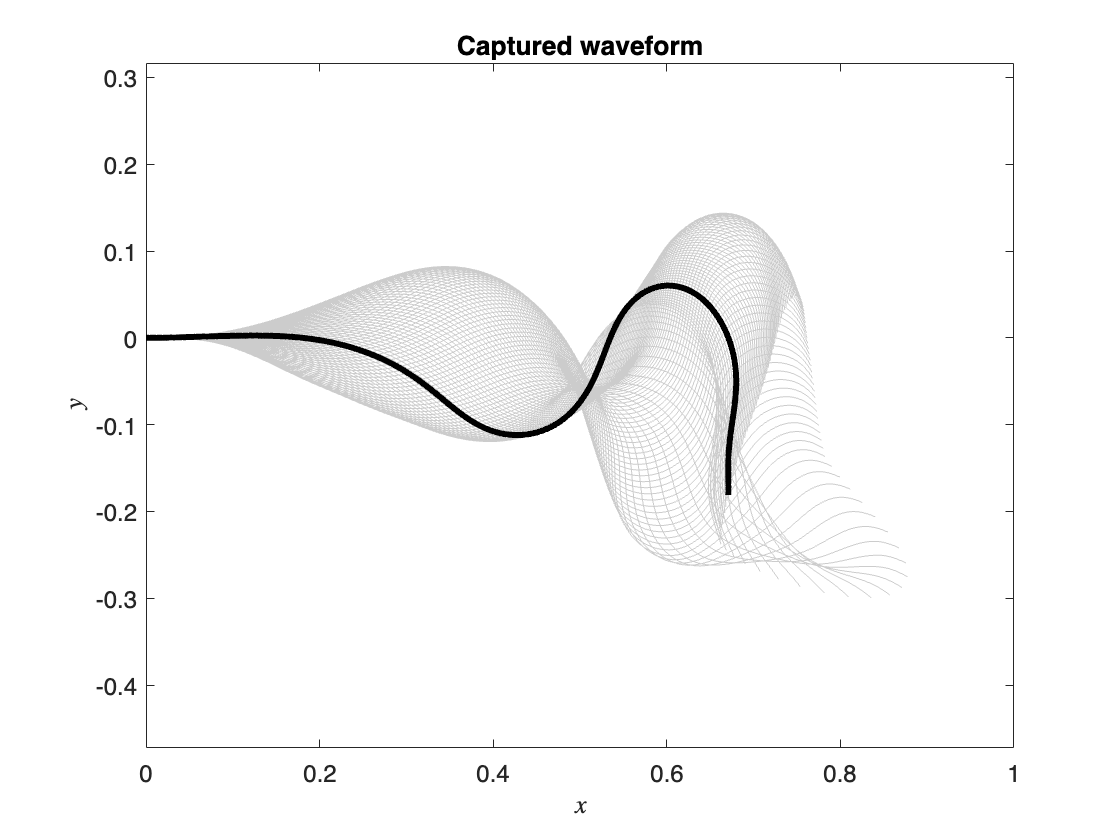

 
swimmerNumber=98;
figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(data{swimmerNumber}.cartesian(:,:,1)',data{swimmerNumber}.cartesian(:,:,2)','color','#cccccc')
    hold on
    % plot the waveform at the current timepoint
    plot(data{swimmerNumber}.cartesian(timepoint,:,1)',data{swimmerNumber}.cartesian(timepoint,:,2)','LineWidth',3,'Color','k')
    axis equal
    xlabel('$x$','interpreter','latex')
    ylabel('$y$','interpreter','latex')
    set(gca,'FontSize',12)
    xlim([0 1])
    set(gca,'XTick',[0 0.2 0.4 0.6 0.8 1])
    title('Captured waveform')
    drawnow
end

Compare sperm waveforms. Input a list of sperm IDs (between 1 and 216), separated by commas. For example: 1,29,167,201 

Then click Run to see them beat over one period.

Note that Sperm IDs from 1 to 79 are from sample A (fresh), and from 80 to 216 are from sample B (thawed).

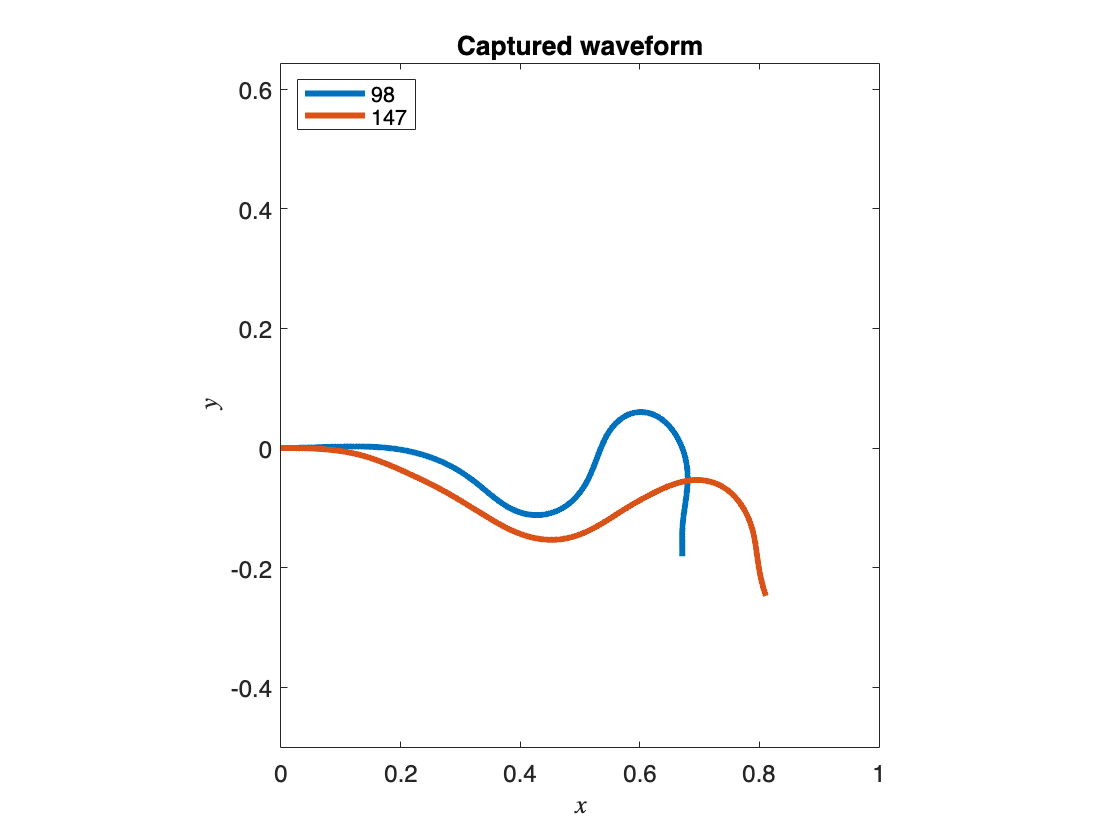

swimmerNumbersInput = "98,147";
  
% try catch - to give a warning message if the user inputs decimals like 1.2 for the
% sperm IDs, for example.
try
    % convert the user's input into an array
    swimmerNumbers = str2num(swimmerNumbersInput);   
    figure
    for timepoint=1:100
        clf
        for i=swimmerNumbers
            % plot the waveform of each swimmer at the current timepoint
            plot(data{i}.cartesian(timepoint,:,1)',data{i}.cartesian(timepoint,:,2)','LineWidth',3)
            hold on
            axis equal
            xlabel('$x$','interpreter','latex')
            ylabel('$y$','interpreter','latex')
            set(gca,'FontSize',12)
            xlim([0 1])
            ylim([waveformMiny,waveformMaxy])
            set(gca,'XTick',[0 0.2 0.4 0.6 0.8 1])
            title('Captured waveform')
            end
        legend(string(swimmerNumbers),'location','northwest')
        drawnow
    end
catch
    warning('Please make sure that the input is a list of sperm IDs (whole numbers between 1 and 216), separated by commas. For example: 1,29,167,201')
end

Watch one sperm cell swim. Select a Sperm ID (from 1 to 216). Note that Sperm IDs from 1 to 79 are from sample A (fresh), and from 80 to 216 are from sample B (thawed).

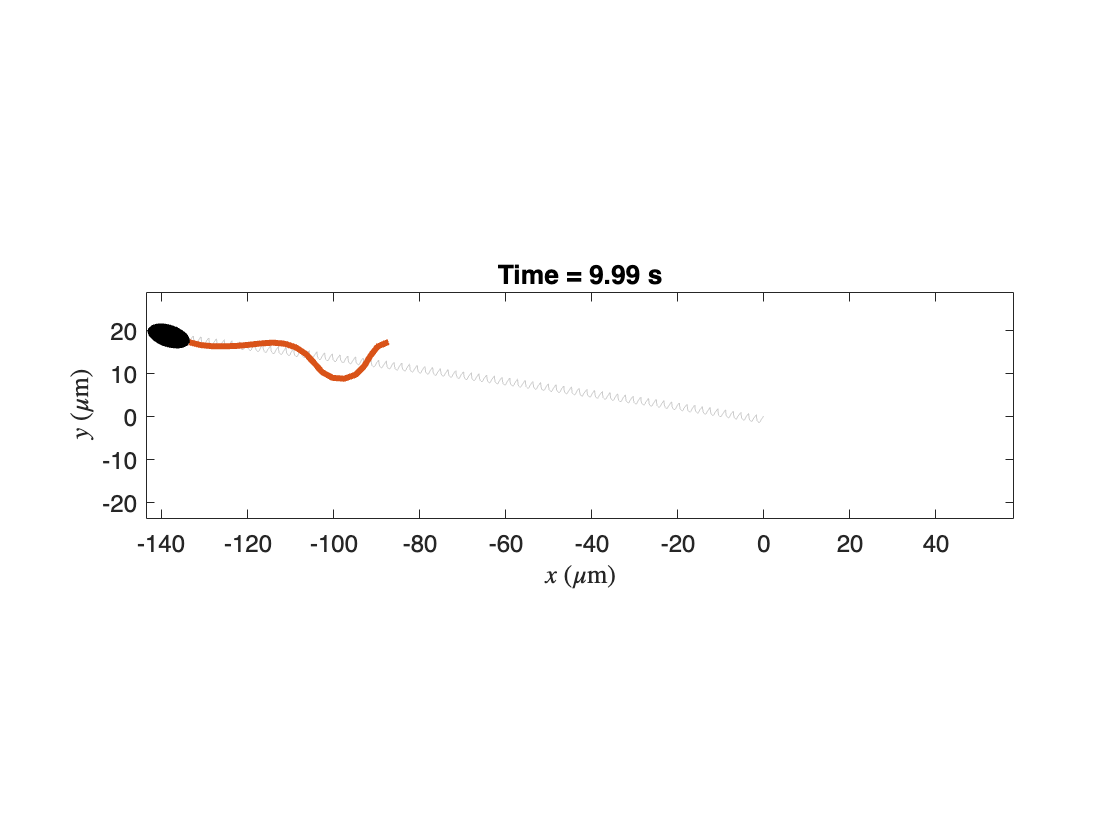

% for drawing the head of the sperm
phiEllipse = linspace(0,2*pi,20);
% centre to the left of the origin so right edge of head is at oriign, 
% major axis 10, minor axis 5 (um)
coordEllipse = [-5+(10/2)*cos(phiEllipse); (5/2)*sin(phiEllipse)];

% user input sperm ID
swimmerNumber=147;
% length of the race
T_end=10;
 

% swim2 function output:
%[ --- x swimmer position -----------;
% ----y swimmer position-------------;
% ----swimmer orientation angle----;
% ----time from 0 to T_end-----------]

% swim2 waveform
% first index gives time, second index gives material point, third index
% gives x or y coordinate

[swim2_output_one, swim2_waveform_one] = swim2(data,swimmerNumber,T_end);

% initialise a cell array for the swimmer heads. Number of rows is the
% number of columns of swim2_output_one, which is the number of timesteps
swimmerEllipseOne = cell(size(swim2_output_one,2),1);

% for xlim and ylim of race in lab frame
xlims = [min(min(swim2_waveform_one(:,:,1)))-10, max(max(swim2_waveform_one(:,:,1)))+10];
ylims = [min(min(swim2_waveform_one(:,:,2)))-10, max(max(swim2_waveform_one(:,:,2)))+10];

% at each timestep
for timeIndex=1:size(swim2_output_one,2)
    % angle of the swimmer
    thetaOne = swim2_output_one(3,timeIndex);
    % rotation matrix for this angle
    rotMatOne = [cos(thetaOne), -sin(thetaOne); sin(thetaOne), cos(thetaOne)];
    % coordinates of outline of sperm head: translate to position of sperm
    % and rotate to orientation of sperm
    swimmerEllipseOne{timeIndex} = [swim2_output_one(1,timeIndex); swim2_output_one(2,timeIndex)] + rotMatOne * coordEllipse;
end

figure
% every 10th timestep 
for timeIndex=1:10:size(swim2_output_one,2)
    clf
    % plot trajectory up to now of the sperm (do not include in legend)
    plot(swim2_output_one(1,1:timeIndex),swim2_output_one(2,1:timeIndex),'color','#cccccc','HandleVisibility','off')
    hold on
    % plot the waveform of the sperm - every 50th material point instead of
    % all 1000 material points, to plot faster.
    plot(swim2_waveform_one(timeIndex,1:50:end,1),swim2_waveform_one(timeIndex,1:50:end,2),'LineWidth',3)
    hold on
    % head of sperm
    fill(swimmerEllipseOne{timeIndex}(1,:),swimmerEllipseOne{timeIndex}(2,:),'k')
    hold on
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    xlim(xlims)
    ylim(ylims)
    set(gca,'FontSize',12)
    % time in seconds to 2 d.p.
    title(['Time = ', num2str(swim2_output_one(4,timeIndex),'%.2f'), ' s'])
    drawnow
end

Input a list of sperm IDs (between 1 and 216), separated by commas. For example: 1,29,167,201 

Note that Sperm IDs from 1 to 79 are from sample A (fresh), and from 80 to 216 are from sample B (thawed).

Then click Race!

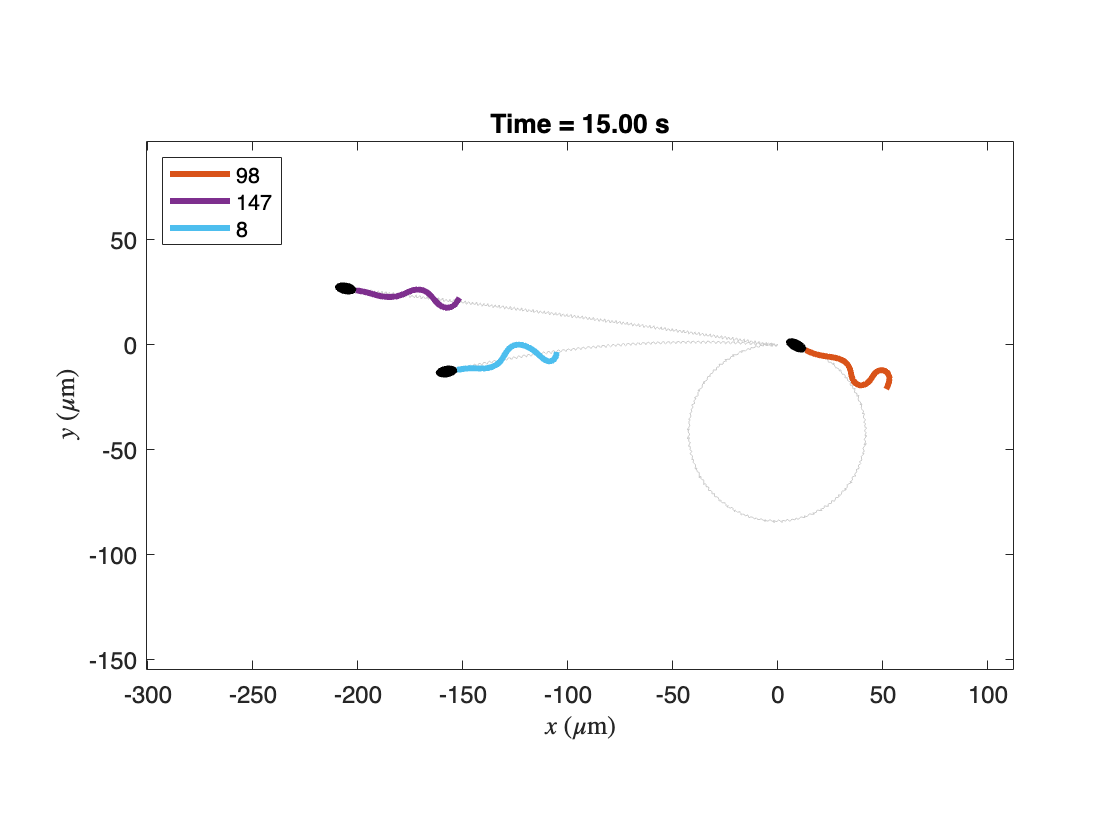

% for drawing head of sperm
phiEllipse = linspace(0,2*pi,100);
% centre to the left of the origin so right edge of head is at oriign, 
% major axis 10, minor axis 5 (um)
coordEllipse = [-5+(10/2)*cos(phiEllipse); (5/2)*sin(phiEllipse)];

% user inputs sperm IDs
swimmerNumbersInput = "98,147,8";
% length of race
T_end=15;
 
% try catch - to display warning if necessary
try
    % convert user input into vector
    swimmerNumbers = str2num(swimmerNumbersInput);    
    
    % initialise cell array to store raw output from swim2 function
    % - one column per sperm
    swimDataRaw = cell(1,length(swimmerNumbers));

    % swim2 produces data for swimmers at different times for each swimmer.
    % To plot the swimmers in the same movie, we need their data at the
    % same times, so we interpolate.

    % initialise cell array to store x position of sperm at the desired times.
    % one column per sperm.
    swimDataxq = cell(1,length(swimmerNumbers));
    % similar for y.
    swimDatayq = cell(1,length(swimmerNumbers));
    % similar for sperm orientation angle theta.
    swimDatathetaq = cell(1,length(swimmerNumbers));

    % desired times for frames of movie, from 0 to length of race, with 20
    % frames per second (a beat period is roughly 0.2 s so this is roughly 4 per
    % period).
    timeq = linspace(0,T_end,T_end*20);

    % initialise cell array to store the outline of each sperm's head at
    % every time. 
    % first index gives timestep, second index is which swimmer.
    swimmerEllipse = cell(length(timeq),length(swimmerNumbers));
    
    % initialise cell array to store waveform of sperm
    % one column per sperm.
    % x coordinates
    swimmerWaveformxq = cell(1,length(swimmerNumbers));
    % y coordinates
    swimmerWaveformyq = cell(1,length(swimmerNumbers));

    for i=1:length(swimmerNumbers)
        % swim2 function output:
        %[ --- x swimmer position -----------;
        % ----y swimmer position-------------;
        % ----swimmer orientation angle----;
        % ----time from 0 to T_end-----------]
        
        % swim2 waveform
        % first index gives time, second index gives material point, third index
        % gives x or y coordinate
        [swim2_output, swim2_waveform] = swim2(data,swimmerNumbers(i),T_end);
        swimDataRaw{i} = swim2_output;
        
        % look at x, y, theta as functions of time, and interpolate.
        xF = griddedInterpolant(swimDataRaw{i}(4,:),swimDataRaw{i}(1,:));
        swimDataxq{i} = xF(timeq);
        yF = griddedInterpolant(swimDataRaw{i}(4,:),swimDataRaw{i}(2,:));
        swimDatayq{i} = yF(timeq);
        thetaF = griddedInterpolant(swimDataRaw{i}(4,:),swimDataRaw{i}(3,:));
        swimDatathetaq{i} = thetaF(timeq);
        
        for timeqIndex=1:length(timeq)
            theta = swimDatathetaq{i}(timeqIndex);
            rotMat = [cos(theta), -sin(theta); sin(theta), cos(theta)];
            % rotate and translate ellipse to orientation and position of
            % sperm
            swimmerEllipse{timeqIndex,i} = [swimDataxq{i}(timeqIndex); swimDatayq{i}(timeqIndex)] + rotMat * coordEllipse;
        end
        
        % interpolate waveform in time too. x is a function of
        % material point and time (similar for y). 
        % treat x(s,t) similarly to "z=f(x,y)", but we
        % only want to interpolate in time, so use same query material points as original.

        matptIndex = 1:size(swim2_waveform,2);
        time = swim2_output(4,:);
        xSwimmer = swim2_waveform(:,:,1);
        % use grid vectors instead of grid for time and material point
        xWaveformF = griddedInterpolant({time,matptIndex},xSwimmer);
        matptIndexq = matptIndex;
        swimmerWaveformxq{i} = xWaveformF({timeq,matptIndexq});

        ySwimmer = swim2_waveform(:,:,2);
        yWaveformF = griddedInterpolant({time,matptIndex},ySwimmer);
        swimmerWaveformyq{i} = yWaveformF({timeq,matptIndexq});

    end
    
    % for xlim and ylim of plot in lab frame
    xlims = [min([swimDataxq{:}]) - 100, max([swimDataxq{:}]) + 70];
    ylims = [min([swimDatayq{:}]) - 70, max([swimDatayq{:}]) + 70];

    figure

    for timeqIndex=1:length(timeq)
        clf
        for i=1:length(swimmerNumbers)
            % trajectory up to now (exclude from legend) in light grey
            plot(swimDataxq{i}(1:timeqIndex),swimDatayq{i}(1:timeqIndex),'color','#cccccc','HandleVisibility','off')
            hold on
            % sperm head
            fill(swimmerEllipse{timeqIndex,i}(1,:),swimmerEllipse{timeqIndex,i}(2,:),'k','HandleVisibility','off')
            hold on
            % waveform
            plot(swimmerWaveformxq{i}(timeqIndex,1:10:end),swimmerWaveformyq{i}(timeqIndex,1:10:end),'LineWidth',3)
            axis equal
            xlabel('$x$ ($\mu$m)','interpreter','latex')
            ylabel('$y$ ($\mu$m)','interpreter','latex')
            set(gca,'FontSize',12)
            xlim(xlims)
            ylim(ylims)
            title(['Time = ', num2str(timeq(timeqIndex),'%.2f'), ' s'])
        end
        legend(string(swimmerNumbers),'location','northwest')
        drawnow
    end
catch
    warning('Something has not worked as expected. Please make sure that the input is a list of sperm IDs (whole numbers between 1 and 216), separated by commas. For example: 11,78,157')
end

Fig. 1(d). Synthetic waveform over a single beat period. Different colours indicate different timepoints within the period.

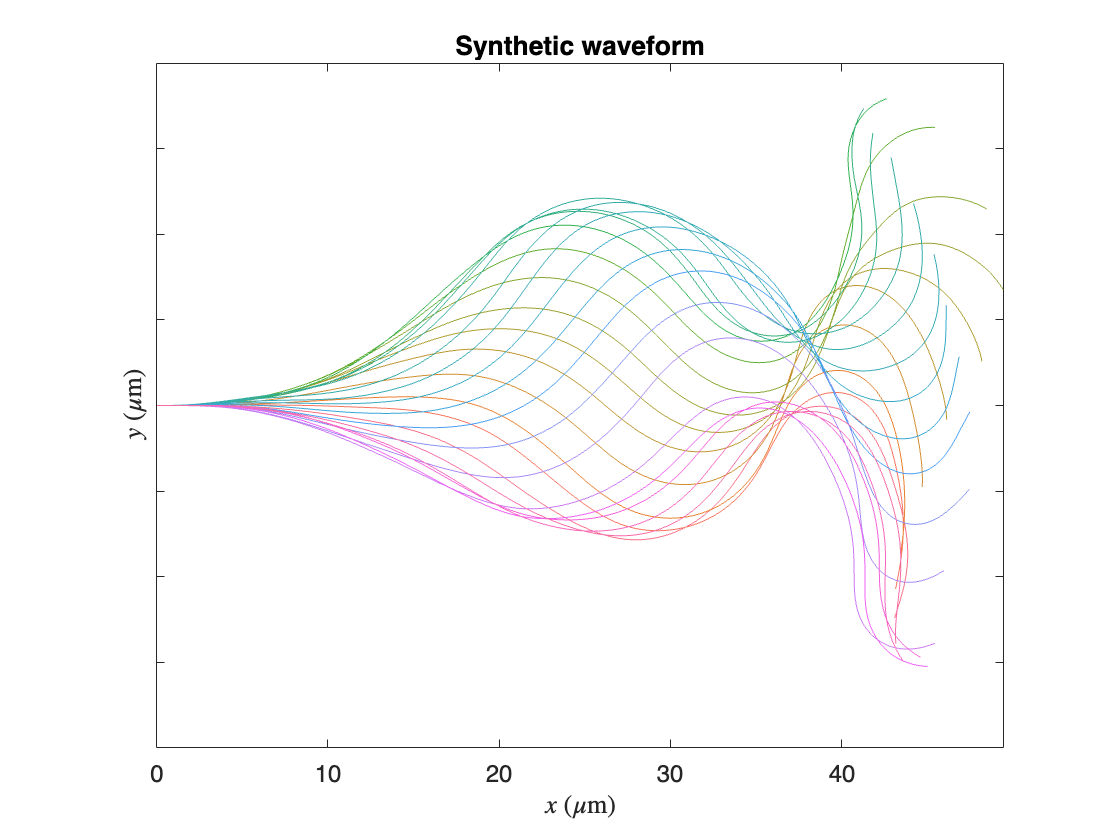

 


figure
h = plot(syntheticBeat.xy(inds,:,1)',syntheticBeat.xy(inds,:,2)');
set(h, {'color'}, num2cell(cc, 2));
axis equal
xlabel('$x$ ($\mu$m)','interpreter','latex')
ylabel('$y$ ($\mu$m)','interpreter','latex')
set(gca,'FontSize',12,'YTickLabel',{})
xlims = [0,49.457];
ylims = [-20,20];
xlim(xlims)
ylim(ylims)
set(gca,'XTick',[0 10 20 30 40])
title('Synthetic waveform')

Animated version of Fig. 1(d). Captured waveform (thick black line) during one beating period. Light grey shows the waveform at all the timepoints during a period.

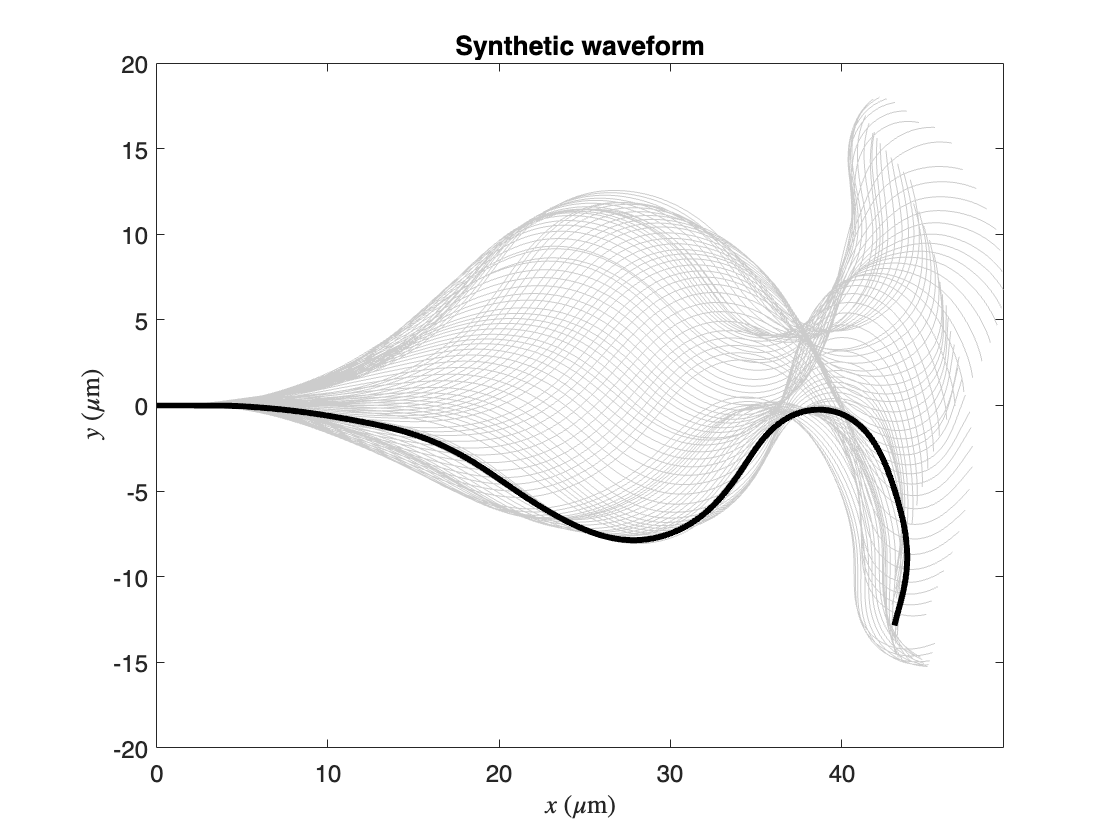


 

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(syntheticBeat.xy(:,:,1)',syntheticBeat.xy(:,:,2)','color','#cccccc')
    hold on
    % plot the current waveform
    plot(syntheticBeat.xy(timepoint,:,1)',syntheticBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',12)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Synthetic waveform')
    drawnow
end

Generate synthetic waveforms. We sample a synthetic waveform using a method that has the same mean and variance as the empirical waveform distribution.

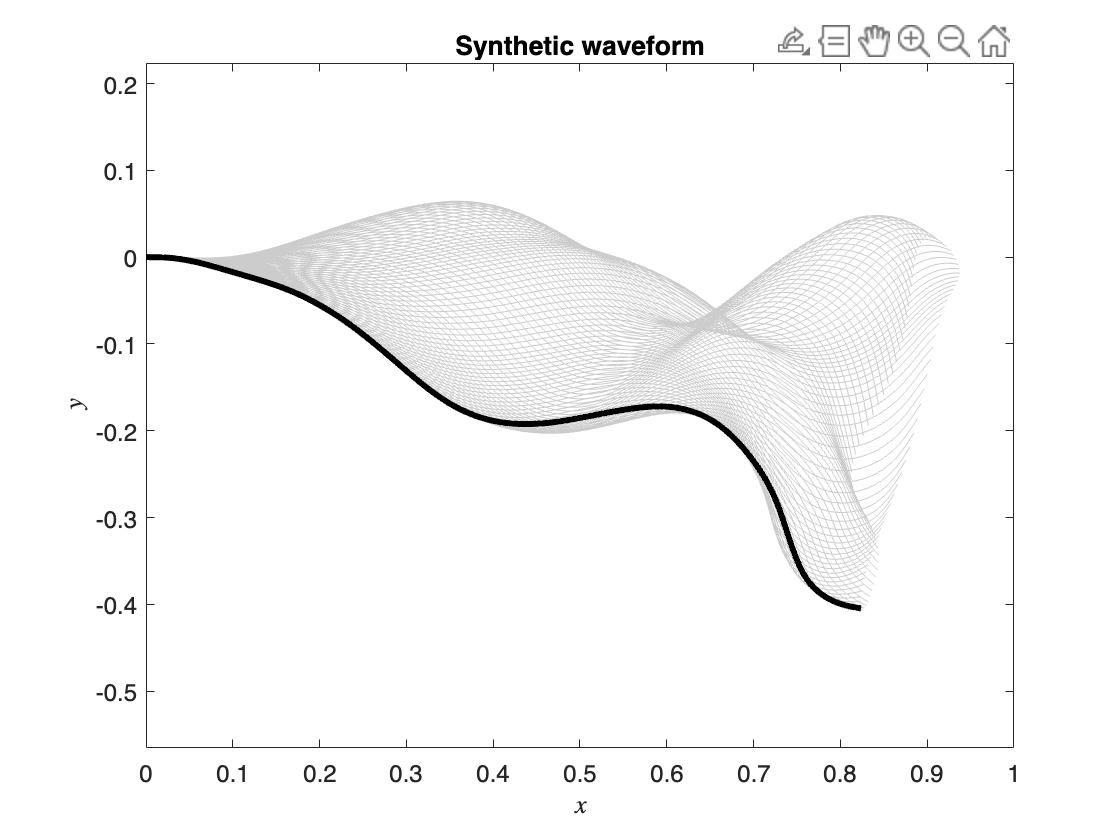

 
randomSynthBeat = synthetic_beat(data);

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(randomSynthBeat.cartesian(:,:,1)',randomSynthBeat.cartesian(:,:,2)','color','#cccccc')
    hold on
    % plot the current waveform
    plot(randomSynthBeat.cartesian(timepoint,:,1)',randomSynthBeat.cartesian(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$','interpreter','latex')
    ylabel('$y$','interpreter','latex')
    set(gca,'FontSize',12)
    xlim([0 1])
    title('Synthetic waveform')
    drawnow
end

## Histogram of swimming speeds

 
load('Data/swimmingspeeds.mat')
load('Data/masks.mat')
bleb_speeds = B_speeds(find(bleb_mask == 1) - 79);
unbleb_speeds = B_speeds(find(unbleb_mask == 1) - 79);

spermid = 3;

if spermid <= 79
    vbar = A_speeds(spermid);
else
    vbar = B_speeds(spermid - 1);
end

disp(['Sperm ' num2str(spermid) ' has average swimming speed = ' num2str(vbar) ' μm^{-1}'])

Sperm 3 has average swimming speed = 8.4544 μm^{-1}


Which sample do you wish to plot?

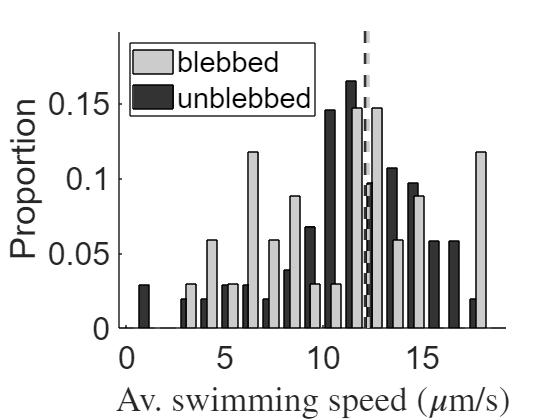

KS p value: 0.1947


sample = 6;
 

if sample == 3

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_speeds,B_speeds]);
maxx = max([A_speeds,B_speeds]);
edges = linspace(0,20,20);
hA = histcounts(A_speeds,edges,'Normalization','probability');
hB = histcounts(B_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])
[h,p] = kstest2(A_speeds,B_speeds);
disp(['KS p value: ',num2str(p)])

elseif sample == 1

figure
hold on
A_col = 0.8;
minx = min([A_speeds]);
maxx = max([A_speeds]);
edges = linspace(0,20,20);
hA = histcounts(A_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_speeds),1,2),[0,max([hA])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample A'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])

elseif sample == 2
%     close all
%     figure
% subplot(3,1,1)
figure
hold on
B_col = 0.2;
minx = min([B_speeds]);
maxx = max([B_speeds]);
edges = linspace(0,20,20);
hB = histcounts(B_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_speeds),1,2),[0,max([hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample B'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])


elseif sample == 6

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_speeds,unbleb_speeds]);
maxx = max([bleb_speeds,unbleb_speeds]);
edges = linspace(0,20,20);
hA = histcounts(bleb_speeds,edges,'Normalization','probability');
hB = histcounts(unbleb_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_speeds),1,2),[0,max([hA,hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])
[h,p] = kstest2(bleb_speeds,unbleb_speeds);
disp(['KS p value: ',num2str(p)])

elseif sample == 4

figure
hold on
A_col = 0.8;
minx = min([bleb_speeds]);
maxx = max([bleb_speeds]);
edges = linspace(0,20,20);
hA = histcounts(bleb_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_speeds),1,2),[0,max([hA])*1.2],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'blebbed'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])

elseif sample == 5

figure
hold on
B_col = 0.2;
minx = min([unbleb_speeds]);
maxx = max([unbleb_speeds]);
edges = linspace(0,20,20);
hB = histcounts(unbleb_speeds,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_speeds),1,2),[0,max([hB])*1.2],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('Av. swimming speed ($\mu$m/s)','interpreter','latex')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'unblebbed'},'Location','northwest')
set(gca,'XTick',[0,5,10,15,20])
end